clearvars; close all; 
imtool close all;

net = resnet101();
imSize = net.Layers(1).InputSize;

trainingFolderPath = "./TrainingData7V4"; 
imds = imageDatastore(trainingFolderPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

[trainDS, testDS, validDS] = splitEachLabel(imds, 0.799, 0.001, 0.2);

validDS = augmentedImageDatastore(imSize(1:2), validDS);
testDS = transform(testDS, @(x) imresize(x, imSize(1:2)));
augmenter = imageDataAugmenter('RandXReflection', true, ...
                               'RandXTranslation', [-50 50], 'RandRotation', [-180 180]);

trainingData = augmentedImageDatastore(imSize(1:2),trainDS,'DataAugmentation',augmenter);

numCats = numel(categories(imds.Labels));

if isa(net, 'SeriesNetwork')
    lgraph = layerGraph(net.Layers);
else
    lgraph = layerGraph(net);
end

lgraph = replaceLayer(lgraph, lgraph.Layers(end-2).Name, fullyConnectedLayer(numCats, 'Name', lgraph.Layers(end-2).Name));
lgraph = replaceLayer(lgraph, lgraph.Layers(end-1).Name, softmaxLayer('Name', lgraph.Layers(end-1).Name));
lgraph = replaceLayer(lgraph, lgraph.Layers(end).Name, classificationLayer('Name', lgraph.Layers(end).Name));

options = trainingOptions('rmsprop','MaxEpochs', 5, ...
    'InitialLearnRate', 0.0001, ...
    'Plots', 'training-progress', ...
    'ValidationData', validDS, ...
    'ValidationFrequency', 5);

trainingData.MiniBatchSize = 256;


convnet = trainNetwork(trainingData, lgraph, options)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


latest_model_name = "FINAL_rps-resnet101_D7V4_epochs5_1.mat";
save(latest_model_name,'convnet');

clearvars; close all; 
imtool close all;

net = resnet50();
imSize = net.Layers(1).InputSize;

trainingFolderPath = "./TrainingData7V4"; 
imds = imageDatastore(trainingFolderPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

[trainDS, testDS, validDS] = splitEachLabel(imds, 0.799, 0.001, 0.2);

validDS = augmentedImageDatastore(imSize(1:2), validDS);
testDS = transform(testDS, @(x) imresize(x, imSize(1:2)));
augmenter = imageDataAugmenter('RandXReflection', true, ...
                               'RandXTranslation', [-50 50], 'RandRotation', [-180 180]);

trainingData = augmentedImageDatastore(imSize(1:2),trainDS,'DataAugmentation',augmenter);

numCats = numel(categories(imds.Labels));

if isa(net, 'SeriesNetwork')
    lgraph = layerGraph(net.Layers);
else
    lgraph = layerGraph(net);
end

lgraph = replaceLayer(lgraph, lgraph.Layers(end-2).Name, fullyConnectedLayer(numCats, 'Name', lgraph.Layers(end-2).Name));
lgraph = replaceLayer(lgraph, lgraph.Layers(end-1).Name, softmaxLayer('Name', lgraph.Layers(end-1).Name));
lgraph = replaceLayer(lgraph, lgraph.Layers(end).Name, classificationLayer('Name', lgraph.Layers(end).Name));

options = trainingOptions('rmsprop','MaxEpochs', 7, ...
    'InitialLearnRate', 0.0001, ...
    'Plots', 'training-progress', ...
    'ValidationData', validDS, ...
    'ValidationFrequency', 5);

trainingData.MiniBatchSize = 256;

convnet = trainNetwork(trainingData, lgraph, options)
latest_model_name = "FINAL_rps-resnet50_D7V4_epochs7_1.mat";
save(latest_model_name,'convnet');

clearvars; close all; 
imtool close all;

net = resnet50();
imSize = net.Layers(1).InputSize;

trainingFolderPath = "./TrainingDataExt"; 
imds = imageDatastore(trainingFolderPath, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

[trainDS, testDS, validDS] = splitEachLabel(imds, 0.799, 0.001, 0.2);

validDS = augmentedImageDatastore(imSize(1:2), validDS);
testDS = transform(testDS, @(x) imresize(x, imSize(1:2)));
augmenter = imageDataAugmenter('RandXReflection', true, ...
                               'RandXTranslation', [-50 50], 'RandRotation', [-180 180]);

trainingData = augmentedImageDatastore(imSize(1:2),trainDS,'DataAugmentation',augmenter);

numCats = numel(categories(imds.Labels));

if isa(net, 'SeriesNetwork')
    lgraph = layerGraph(net.Layers);
else
    lgraph = layerGraph(net);
end

lgraph = replaceLayer(lgraph, lgraph.Layers(end-2).Name, fullyConnectedLayer(numCats, 'Name', lgraph.Layers(end-2).Name));
lgraph = replaceLayer(lgraph, lgraph.Layers(end-1).Name, softmaxLayer('Name', lgraph.Layers(end-1).Name));
lgraph = replaceLayer(lgraph, lgraph.Layers(end).Name, classificationLayer('Name', lgraph.Layers(end).Name));

options = trainingOptions('rmsprop','MaxEpochs', 5, ...
    'InitialLearnRate', 0.0001, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.2, ...
    'Plots', 'training-progress', ...
    'LearnRateDropPeriod', 1, ...
    'ValidationData', validDS, ...
    'ValidationFrequency', 1);

trainingData.MiniBatchSize = 5;

%convnet = trainNetwork(trainingData, lgraph, options)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:33 |       95.06% |       75.00% |       0.1193 |       0.5743 |      1.0000e-04 |
|       2 |           2 |       00:01:01 |       97.53% |       85.00% |       0.2073 |       0.5137 |      2.0000e-05 |
|       3 |           3 |       00:01:29 |      100.00% |       85.00% |       0.0067 |       0.5109 |      4.0000e-06 |
|       4 |           4 |       00:02:06 |      100.00% |       85.00% |       0.0015 |   

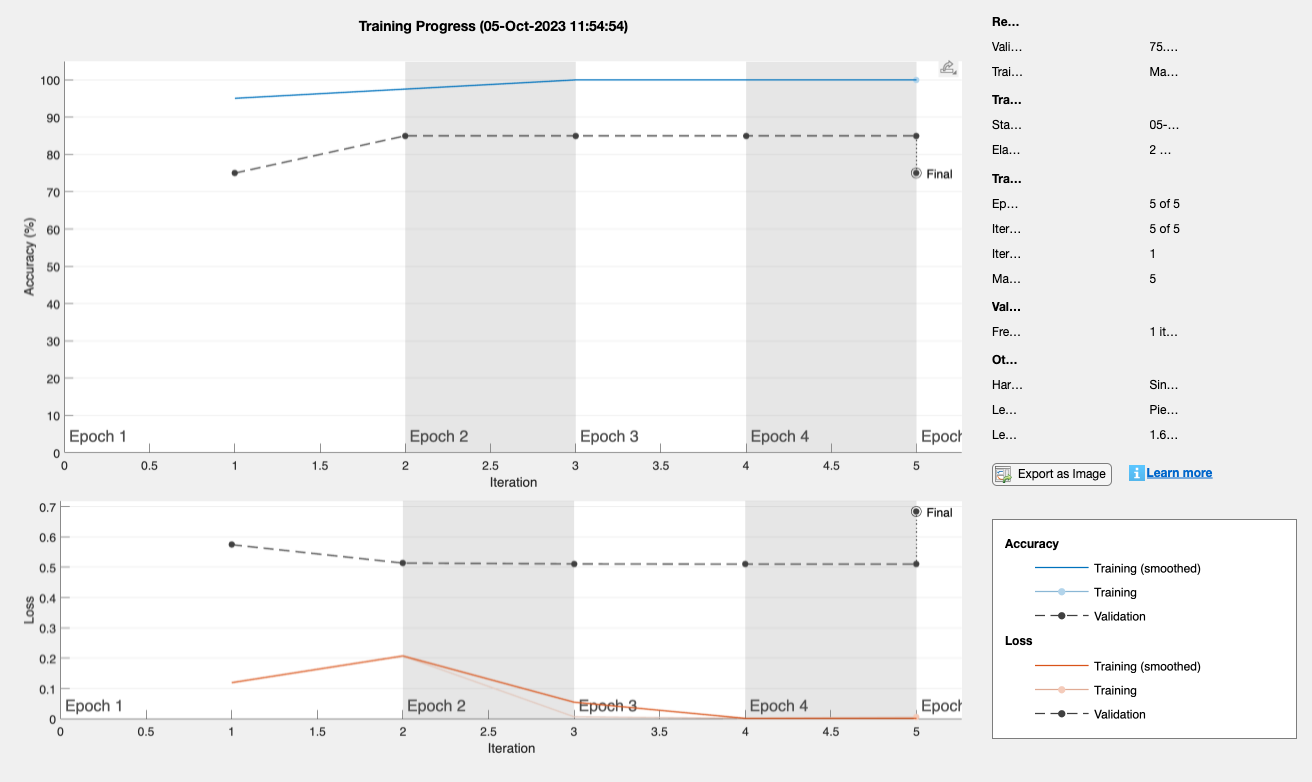

netPre = coder.loadDeepLearningNetwork('rps-resnet50_D7V4_epochs5_1.mat');
convnet = trainNetwork(trainingData, layerGraph(netPre), options);

latest_model_name = "FINAL_rps-resnet50_DExt_epochs5V4+15_2.mat";
save(latest_model_name,'convnet');